# Dummy maps for cue effect

Model (6cond with high/low cue & rampup/rampdown)

parameter:

- 18 **S**timulus onset

- `    cue ``H``igh x stim ``H``igh (plateau onset)`

- `        cue ``H``igh x stim ``H``igh (rampup onset)`

- `        cue ``H``igh x stim ``H``igh (rampdown onset)`

- `    cue ``H``igh x stim ``M``ed`

- `        cue ``H``igh x stim ``M``ed (rampup onset)`

- `        cue ``H``igh x stim ``M``ed (rampdown onset)`

- `    cue ``H``igh x stim ``L``ow`

- `        ... (rampup onset)`

- `        ... (rampdown onset)`

- `    cue ``L``ow x stim ``H``igh`

- `        ... (rampup onset)`

- `        ... (rampdown onset)`

- `    cue ``L``ow x stim ``M``ed`

- `        ... (rampup onset)`

- `        ... (rampdown onset)`

- `    cue ``L``ow x stim ``L``ow`

- `        ... (rampup onset)`

- `        ... (rampdown onset)`

- `2 C``ue: onset01_cue`

- `    cue High`

- `    cue Low`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain only dummy maps 

# cue effect (high > low)

#### Pain only :: load dataset

clear all;
close all;

contrast_of_interest = 'P_simple_CUE_cue_high_gt_low'

contrast_of_interest = 'P_simple_CUE_cue_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 2.227995 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6888657  Bit rate: 22.72 bits


#### Pain only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:05:36 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Pain only :: Plot diagnostics, before l2norm

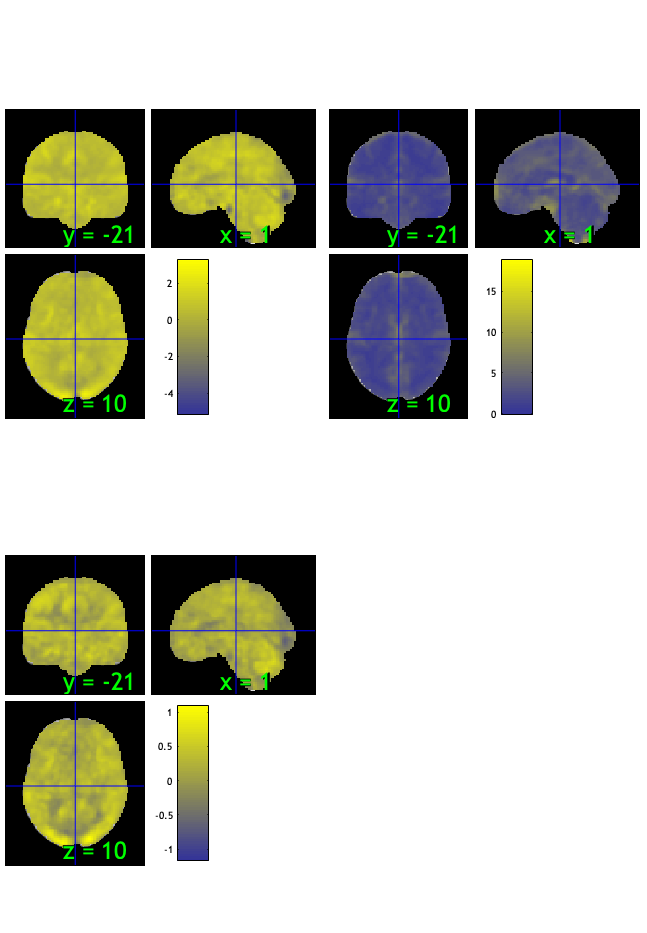

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 29.17%
Expected 3.60 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 36 44 
Uncorrected: 5 images		Cases 8 36 44 61 68 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 54.17%
Expected 3.60 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               _____

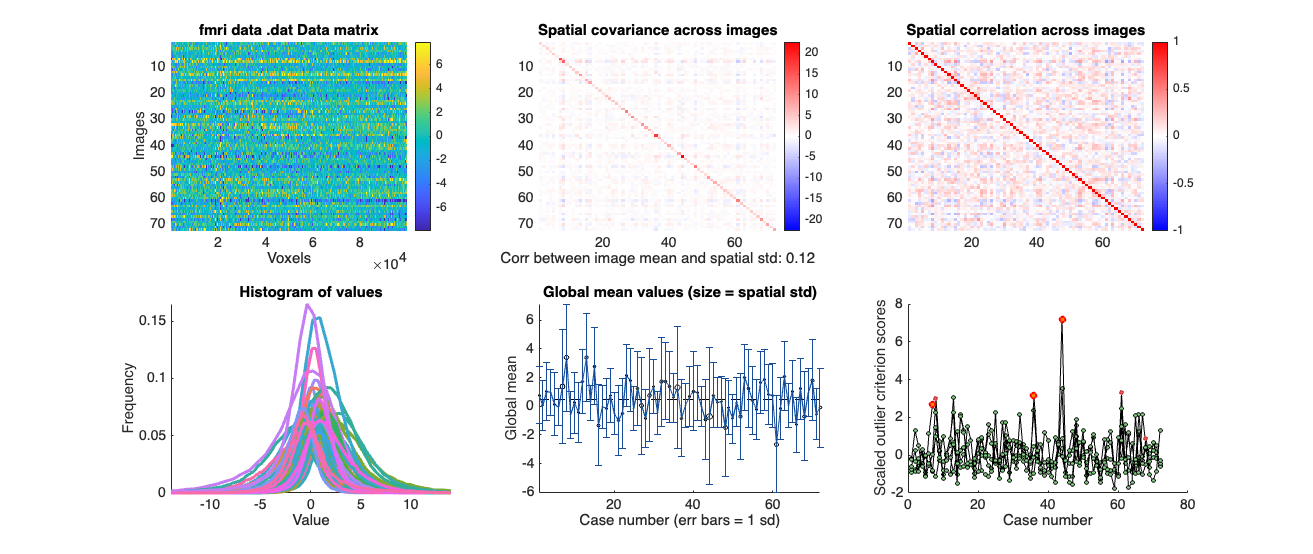

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:05:58 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

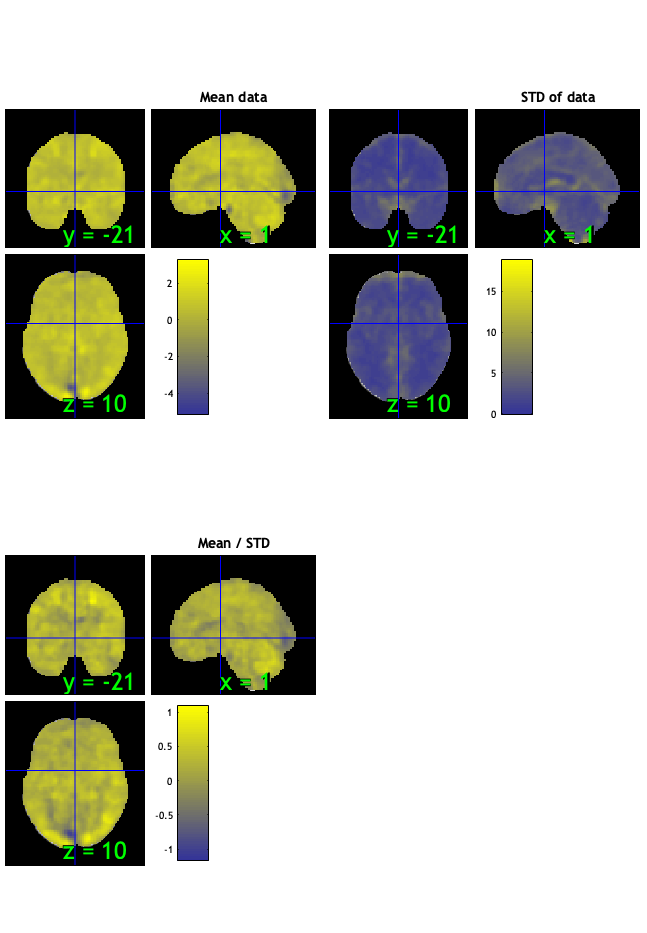

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain only :: run robfit

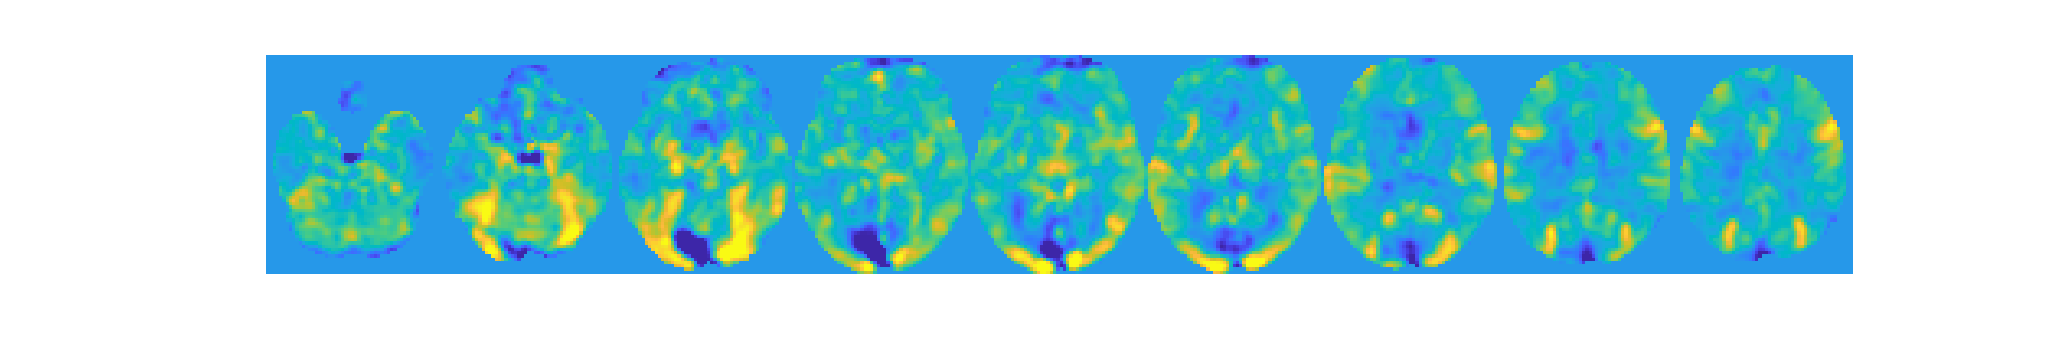

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 69


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0033"    "participants that are outliers:... sub-0082"    "participants that are outliers:... sub-0093"



disp(n);

    {'sub-0033'}    {'sub-0082'}    {'sub-0093'}



#### Pain only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


orthviews(t);

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:06:04 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


drawnow, snapnow;

unc_t = threshold(t, .01, 'unc');


Image   1
 67 contig. clusters, sizes   1 to 22915
Positive effect: 23028 voxels, min p-value: 0.00000000
Negative effect: 766 voxels, min p-value: 0.00000000


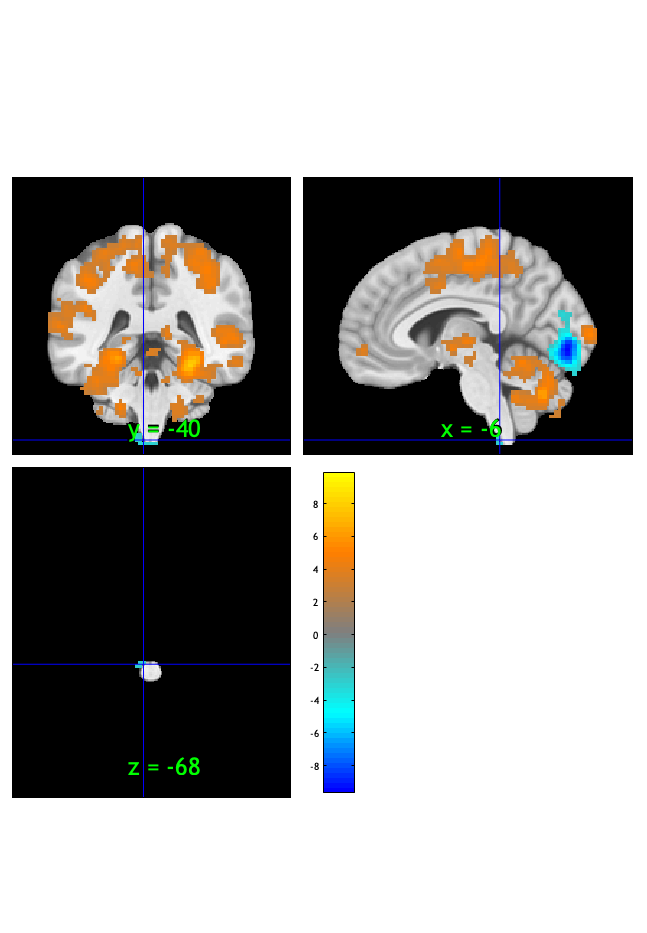

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:06:06 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(unc_t);

drawnow, snapnow;



fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.012881

Image   1
 67 contig. clusters, sizes   1 to 24675
Positive effect: 24886 voxels, min p-value: 0.00000000
Negative effect: 834 voxels, min p-value: 0.00000000


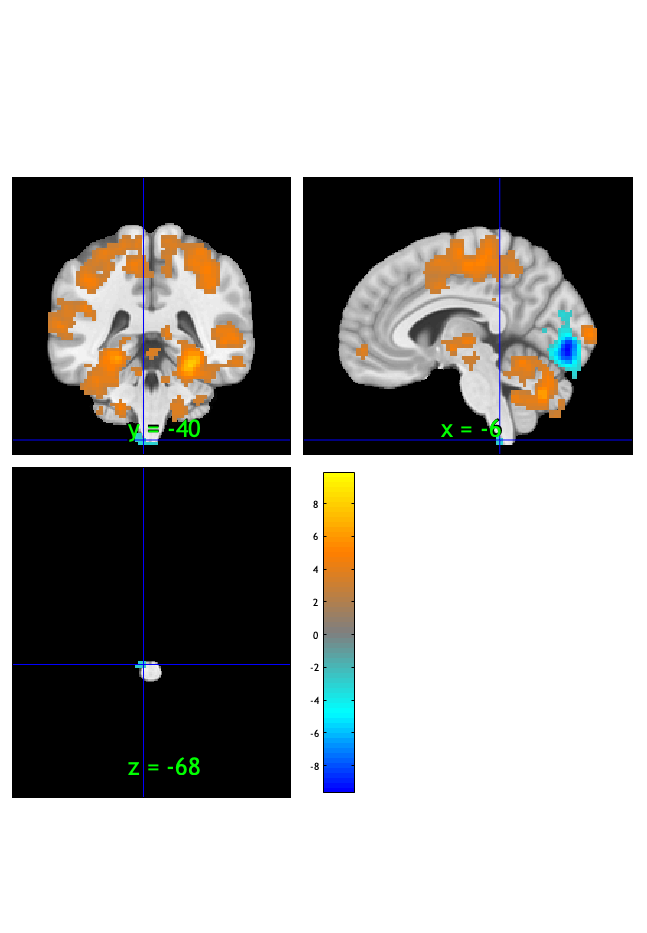

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:06:06 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000057

Image   1
 70 contig. clusters, sizes   1 to 2253
Positive effect: 5385 voxels, min p-value: 0.00000000
Negative effect: 283 voxels, min p-value: 0.00000000


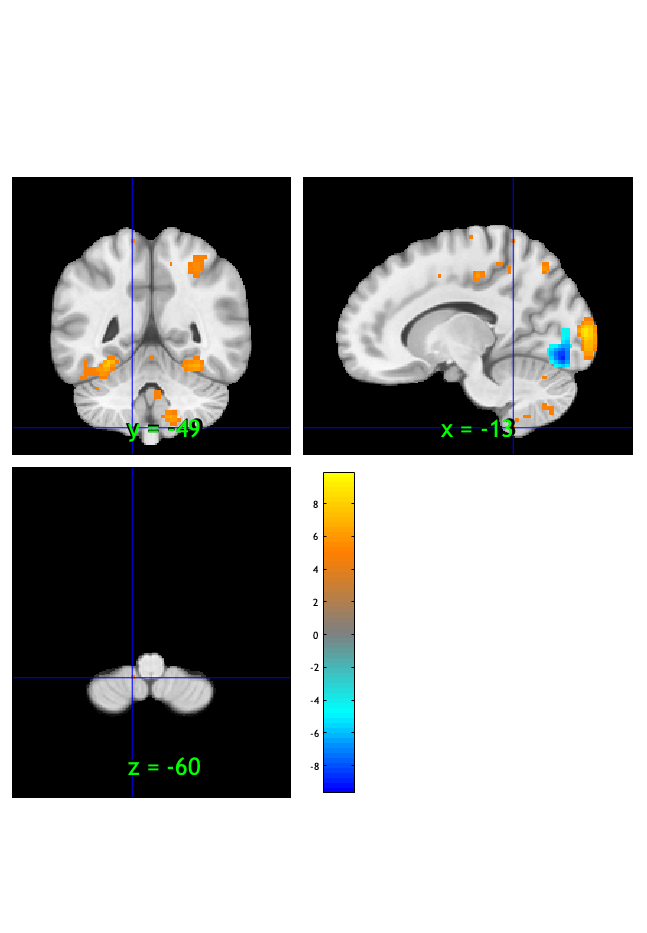

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:06:07 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


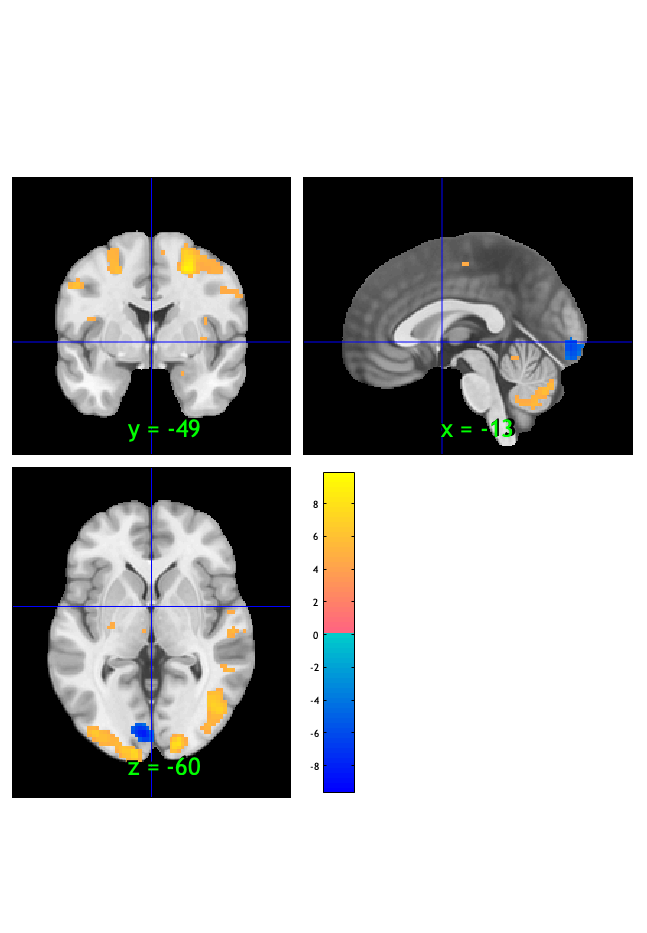

orthviews(fdr_t);

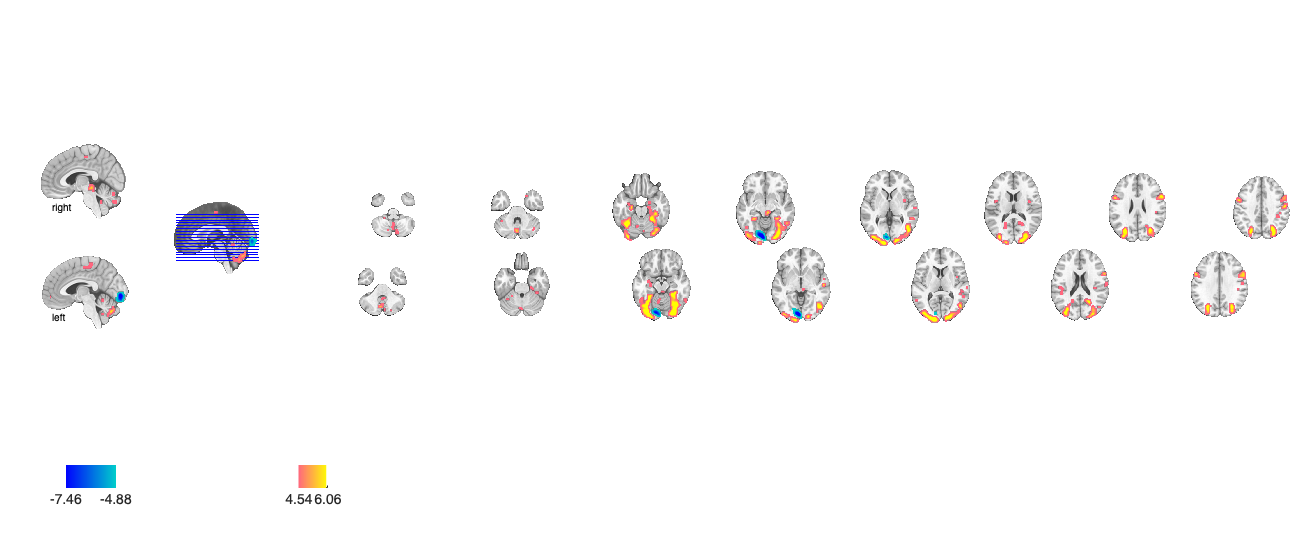

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage:  63 voxels displayed, 5605 not displayed on these slices
sagittal montage:  25 voxels displayed, 5643 not displayed on these slices
sagittal montage:  53 voxels displayed, 5615 not displayed on these slices
axial montage: 1053 voxels displayed, 4615 not displayed on these slices
axial montage: 1244 voxels displayed, 4424 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Pain only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high       words_high   
    _________    _________________    __________    ________________

    -0.21622     {'trait'        }     0.18114      {'execution'   }
    -0.21134     {'disorder'     }     0.17163      {'planning'    }
    -0.20181     {'age'          }        0.17      {'movements'   }
    -0.15887     {'depression'   }     0.15848      {'gesture'     }
    -0.15676     {'schizophrenia'}      0.1578      {'naming'      }
    -0.14907     {'risk'         }     0.15745      {'solving'     }
    -0.14624     {'association'  }     0.15585      {'visual'      }
    -0.14515     {'personal'     }     0.15124      {'preparatory' }
    -0.14188     {'time'         }     0.15095      {'motor'       }
 

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0120	-2.2896	0.0250	1.0000	*
Cog Wholebrain	-0.0022	-0.4983	0.6198	0.0000	
Emo Wholebrain	0.0133	2.5868	0.0117	1.0000	*
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    ________    ________    ________

    {'Pain Wholebrain'}     -0.011998    0.0052414      -2.289    0.025057    -0.26976
    {'Cog Wholebrain' }    -0.0021775    0.0043443    -0.50122     0.61776    -0.05907
    {'Emo Wholebrain' }      0.013306      0.00514      2.5886    0.011681     0.30507



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [19.0006 20.0006 21.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d 
    ___________________    __________    _________    ________    ________    _________

    {'Pain Wholebrain'}      -0.01082    0.0051382     -2.1057    0.038765     -0.24816
    {'Cog Wholebrain' }    -0.0016159    0.0040476    -0.39923     0.69092    -0.047049
    {'Emo Wholebrain' }      0.011855    0.0049794      2.3808    0.019962      0.28058



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [22.0006 23.0006 24.0006]


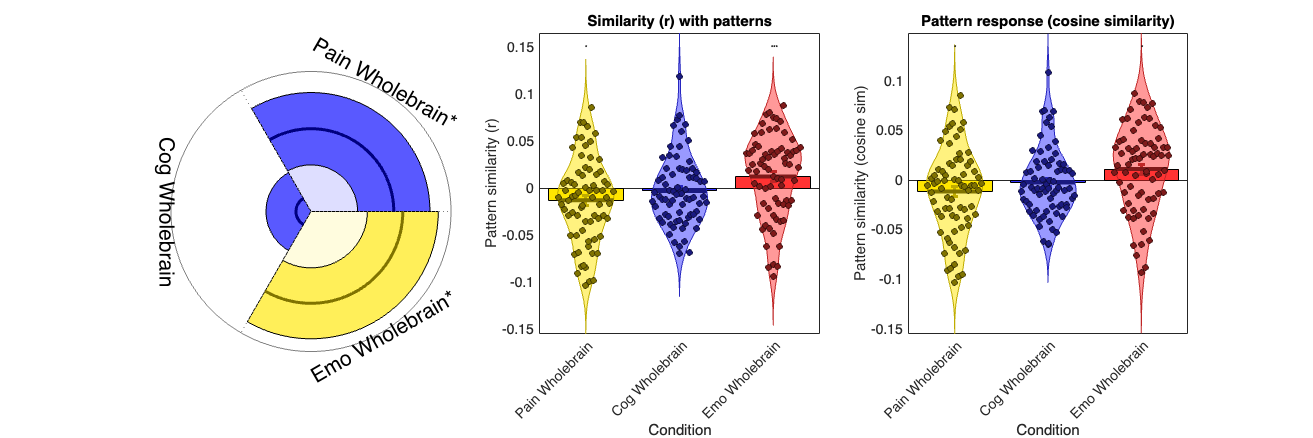

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious only dummy maps 

# cue effect (high > low)

#### Vicarious only :: load dataset

clear all;
close all;

contrast_of_interest = 'V_simple_CUE_cue_high_gt_low';
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 3.602907 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6903362  Bit rate: 22.72 bits


#### Vicarious only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:06:43 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious only :: Plot diagnostics, before l2norm

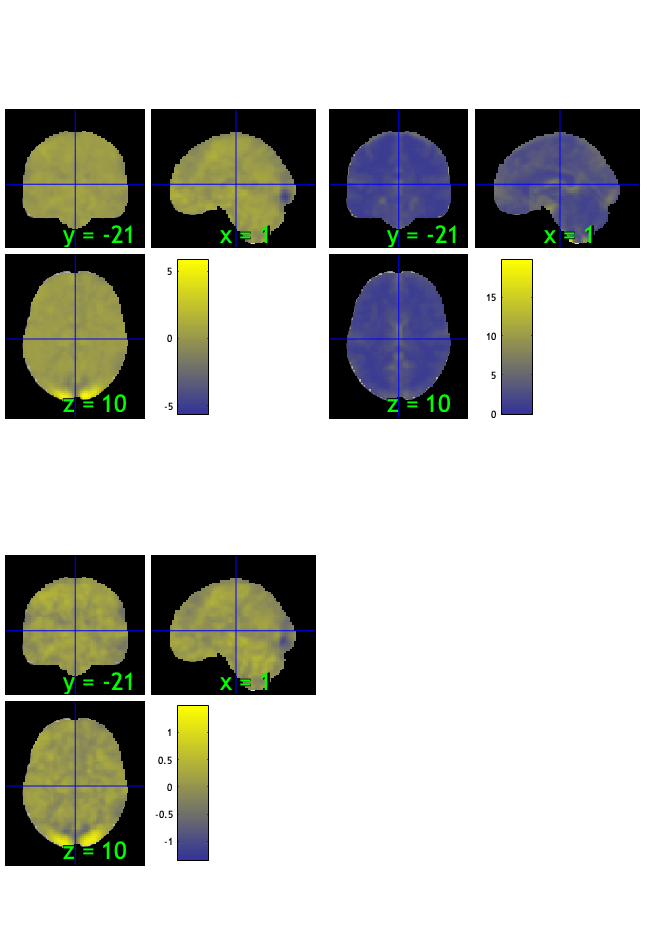

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 27.78%
Expected 3.60 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 34 39 48 
Uncorrected: 6 images		Cases 18 34 36 39 48 60 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.83%
Expected 3.60 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 38 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               

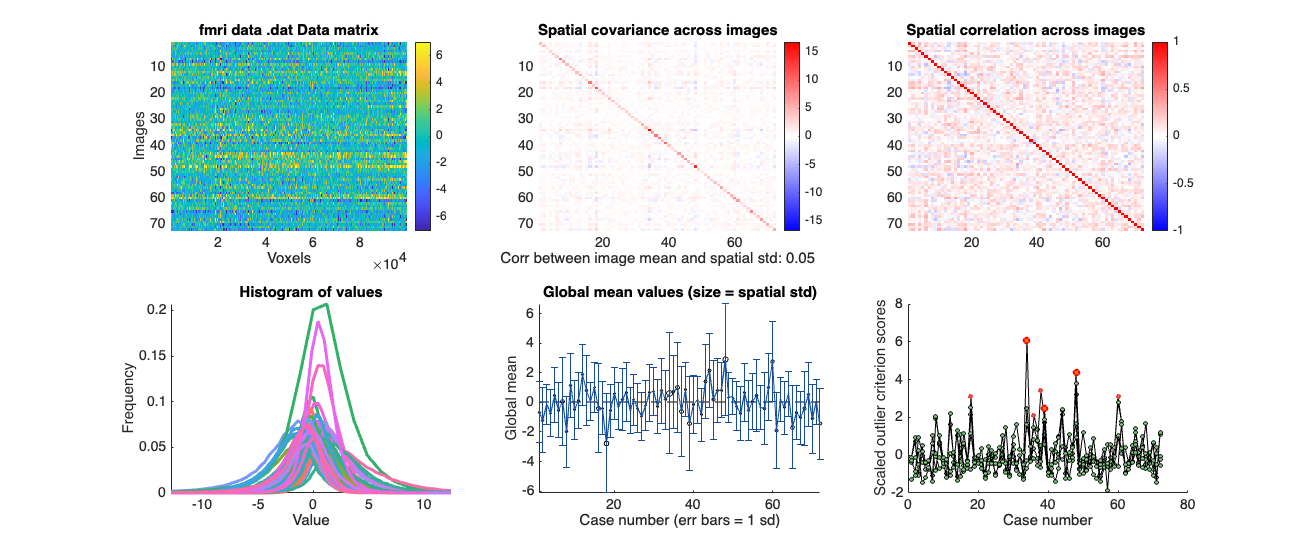

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:07:08 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious only :: run robfit

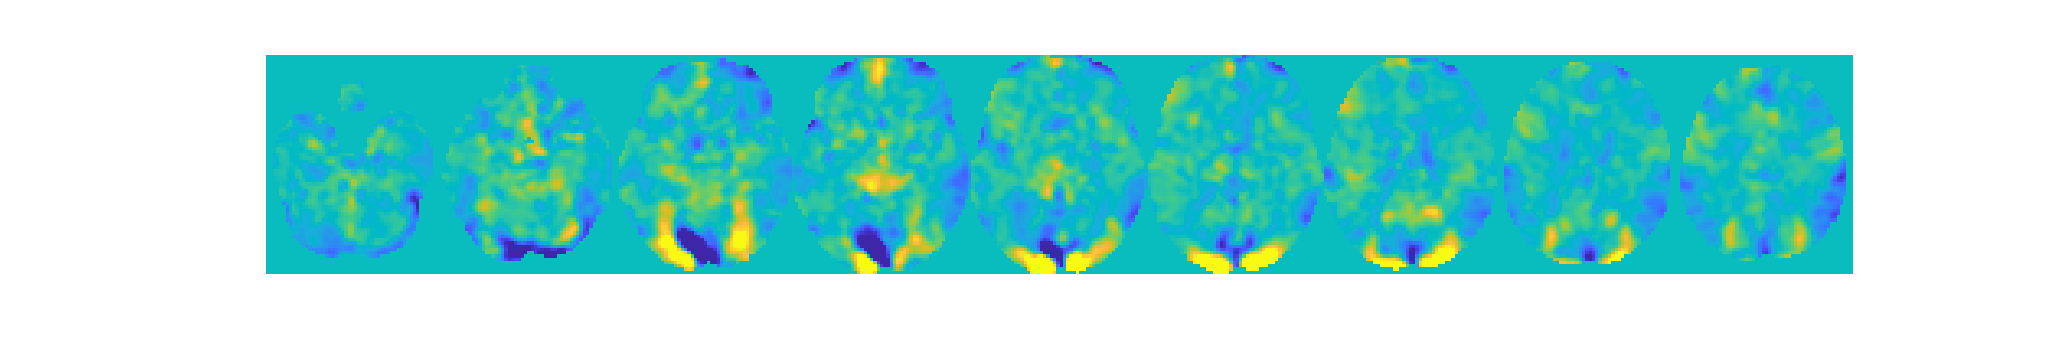

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 69


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0080"    "participants that are outliers:... sub-0086"    "participants that are outliers:... sub-0098"



disp(n);

    {'sub-0080'}    {'sub-0086'}    {'sub-0098'}



#### Vicarious only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


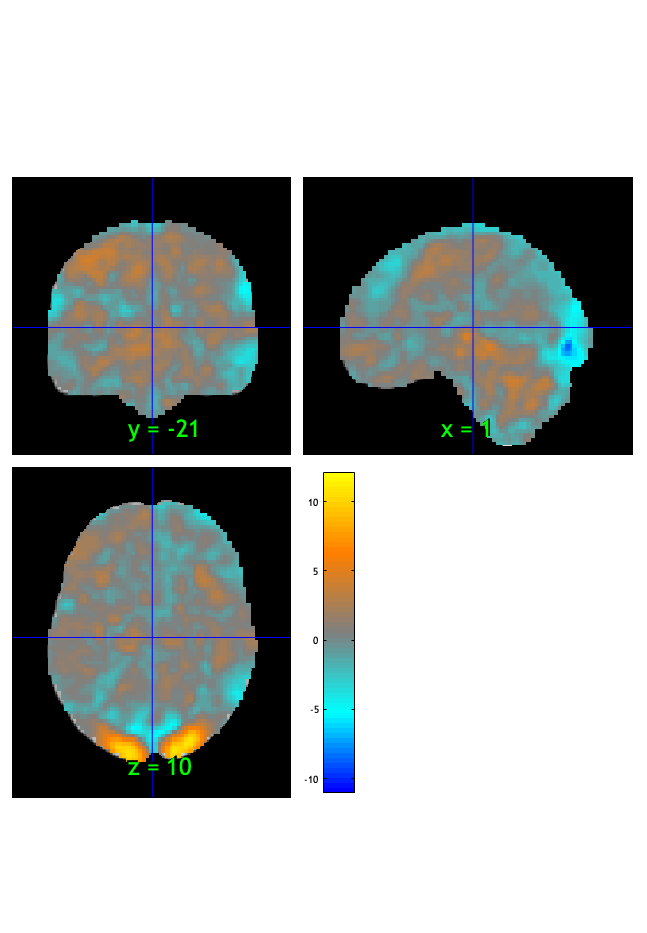

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:07:11 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.003984

Image   1
 89 contig. clusters, sizes   1 to 2559
Positive effect: 4665 voxels, min p-value: 0.00000000
Negative effect: 3288 voxels, min p-value: 0.00000000


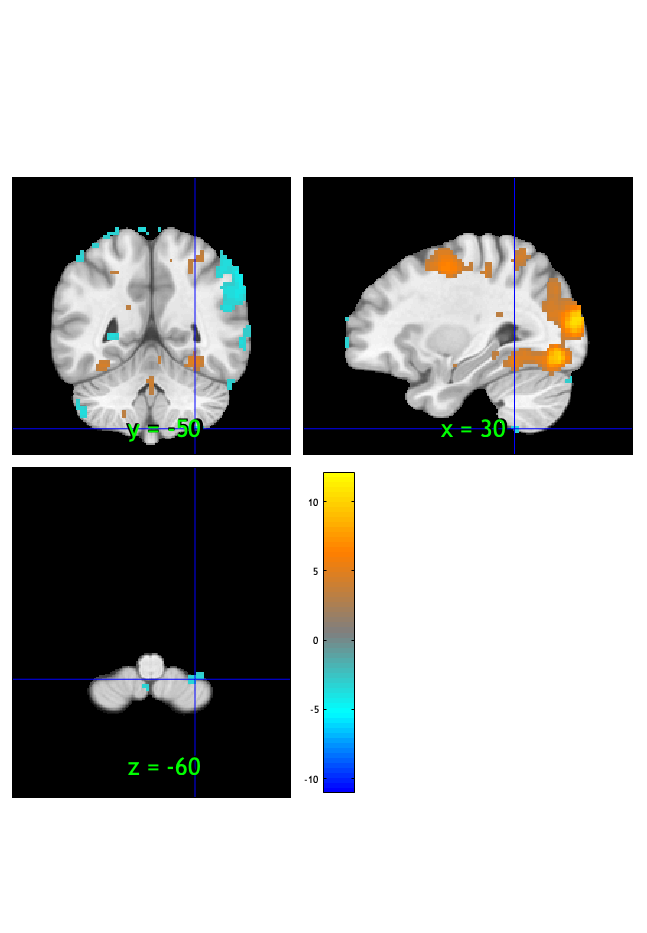

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:07:12 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


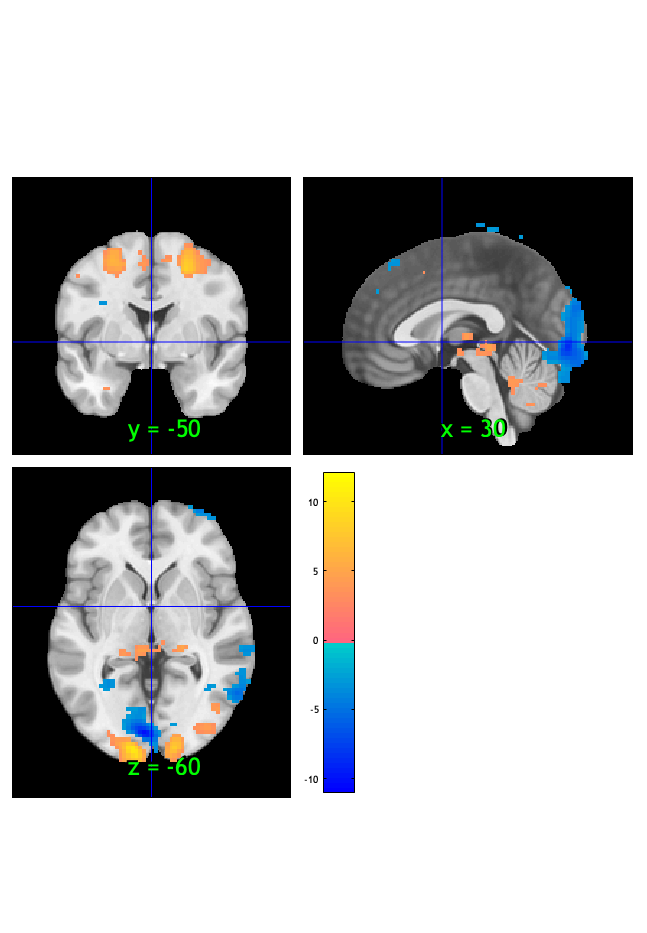

orthviews(fdr_t);

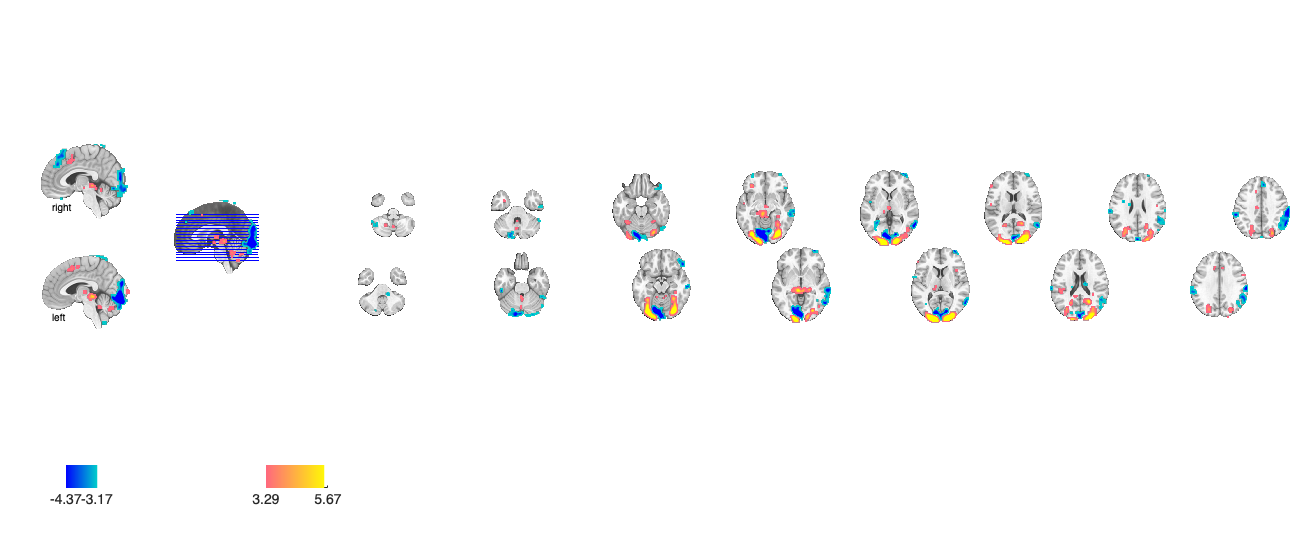

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 192 voxels displayed, 7761 not displayed on these slices
sagittal montage: 160 voxels displayed, 7793 not displayed on these slices
sagittal montage: 175 voxels displayed, 7778 not displayed on these slices
axial montage: 1499 voxels displayed, 6454 not displayed on these slices
axial montage: 1658 voxels displayed, 6295 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Vicarious only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high      words_high  
    _________    _________________    __________    ______________

     -0.13538    {'disorder'     }     0.13331      {'visual'    }
     -0.13416    {'trait'        }     0.12407      {'naming'    }
     -0.12061    {'person'       }     0.12169      {'execution' }
     -0.12016    {'restingstate' }     0.11943      {'overt'     }
     -0.11851    {'judgments'    }     0.11615      {'rotation'  }
     -0.10724    {'personal'     }     0.11509      {'autistic'  }
     -0.10709    {'schizophrenia'}     0.11007      {'motor'     }
     -0.10364    {'social'       }     0.10889      {'movements' }
    -0.097579    {'negative'     }     0.10687      {'covert'    }
    -0.096848    {'pers

Vicarious only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0221	-2.8540	0.0057	1.0000	**
Cog Wholebrain	0.0151	4.4494	0.0000	1.0000	***
Emo Wholebrain	0.0074	1.1644	0.2482	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}     -0.02211     0.0077485    -2.8535    0.0056627    -0.33628
    {'Cog Wholebrain' }     0.015141     0.0034034     4.4489    3.127e-05     0.52431
    {'Emo Wholebrain' }    0.0073655     0.0063273     1.1641      0.24829     0.13719



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [19.0007 20.0007 21.0007]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.022267     0.0073601    -3.0254     0.0034566    -0.35654
    {'Cog Wholebrain' }     0.014787     0.0032823     4.5051    2.5479e-05     0.53093
    {'Emo Wholebrain' }    0.0077107     0.0059943     1.2863       0.20251      0.1516



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [22.0007 23.0007 24.0007]


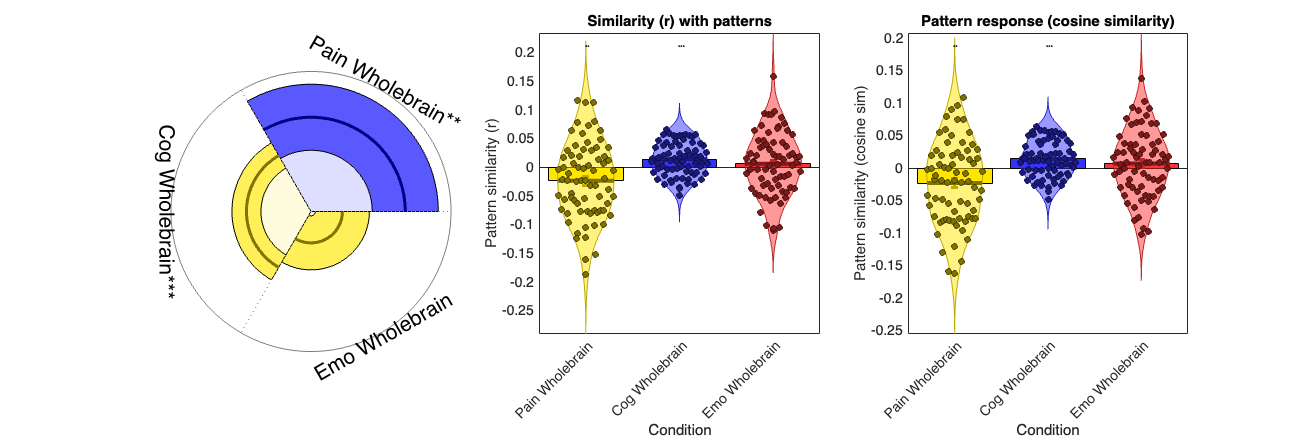

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive only dummy maps 

# cue effect (high > low)

#### Cognitive only :: load dataset

clear all;
close all;

contrast_of_interest = 'C_simple_CUE_cue_high_gt_low'

contrast_of_interest = 'C_simple_CUE_cue_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 3.540450 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6902529  Bit rate: 22.72 bits


#### Cognitive only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:07:50 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Cognitive only :: Plot diagnostics, before l2norm

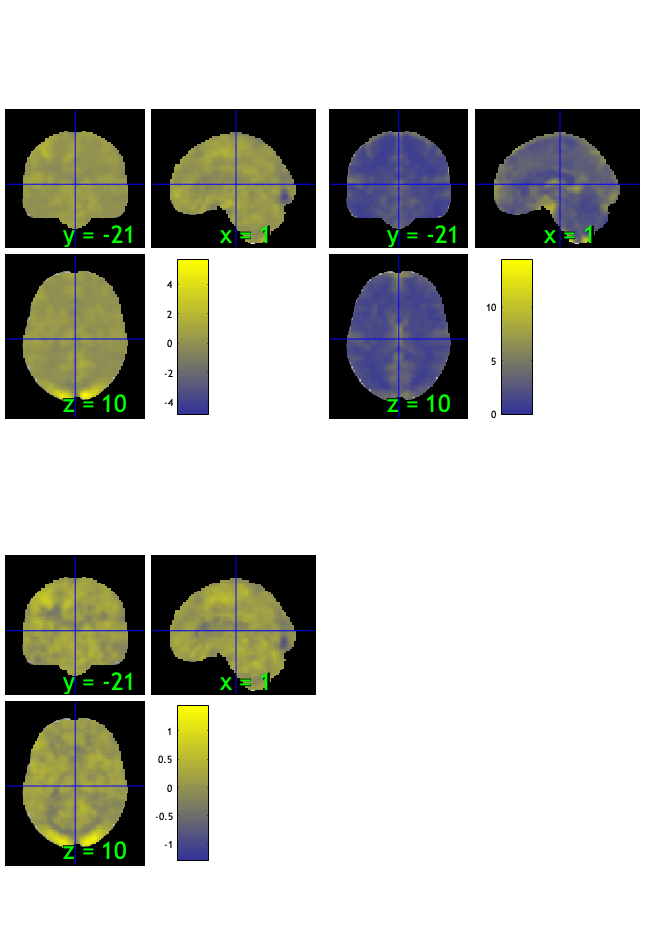

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.83%
Expected 3.60 outside 95% ellipsoid, found   8

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 8 36 37 39 44 
Uncorrected: 8 images		Cases 8 18 36 37 39 44 48 65 

Retained 15 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.61%
Expected 3.60 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
                          

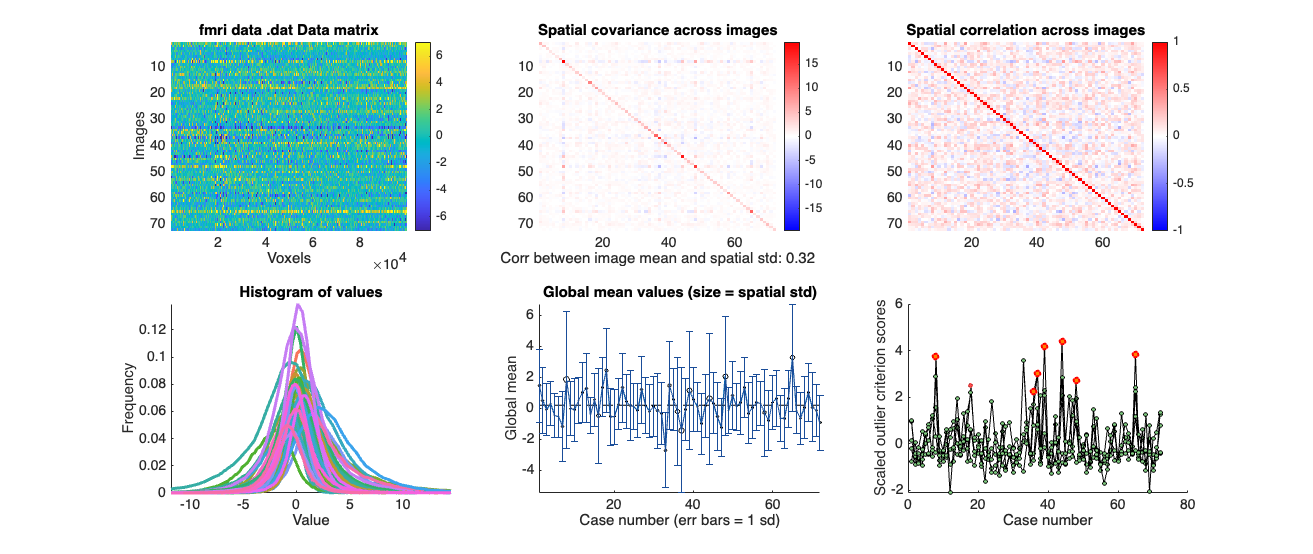

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:08:17 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive only :: run robfit

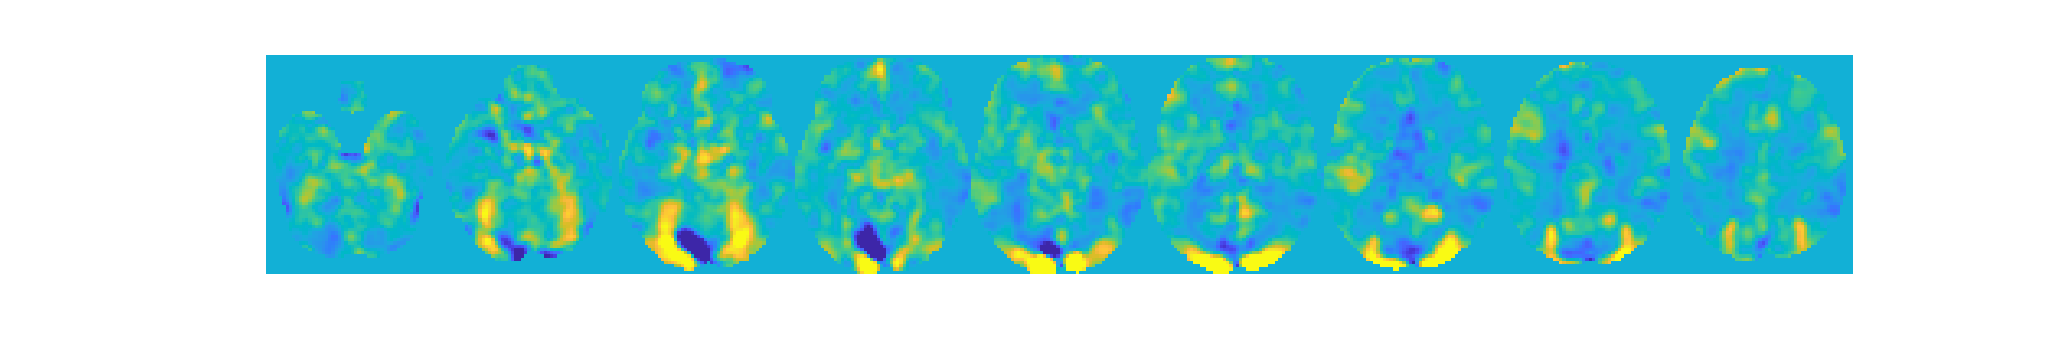

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 7 participants, size is now 65


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are ou…"    "participants that are ou…"    "participants that are ou…"    "participants that are ou…"    "participants that are ou…"    "participants that are ou…"    "participants that are ou…"



disp(n);

    {'sub-0035'}    {'sub-0082'}    {'sub-0084'}    {'sub-0086'}    {'sub-0093'}    {'sub-0098'}    {'sub-0123'}



#### Cognitive only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


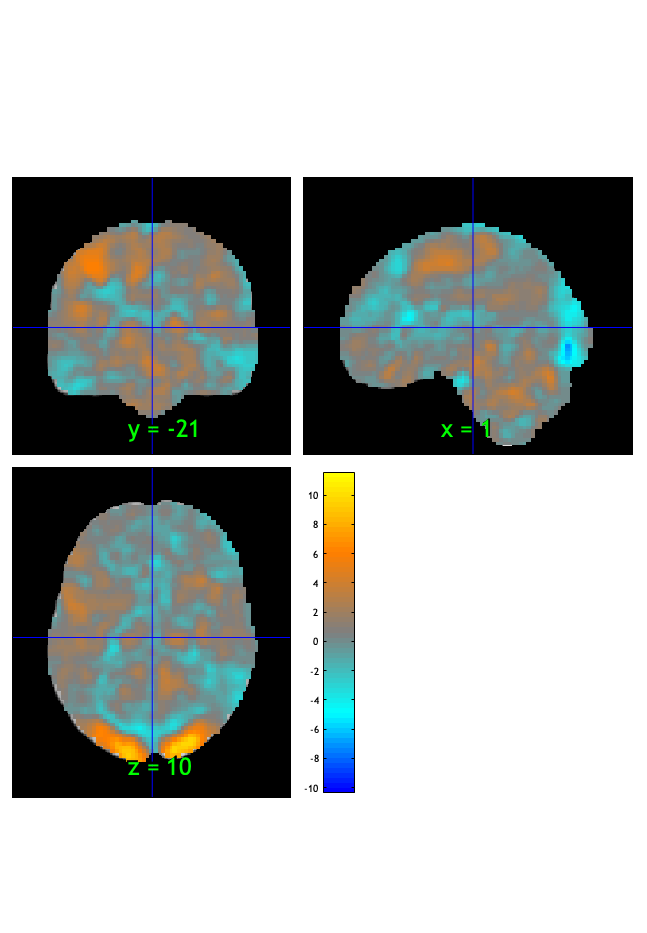

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:08:20 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.004030

Image   1
 87 contig. clusters, sizes   1 to 2671
Positive effect: 6886 voxels, min p-value: 0.00000000
Negative effect: 1160 voxels, min p-value: 0.00000000


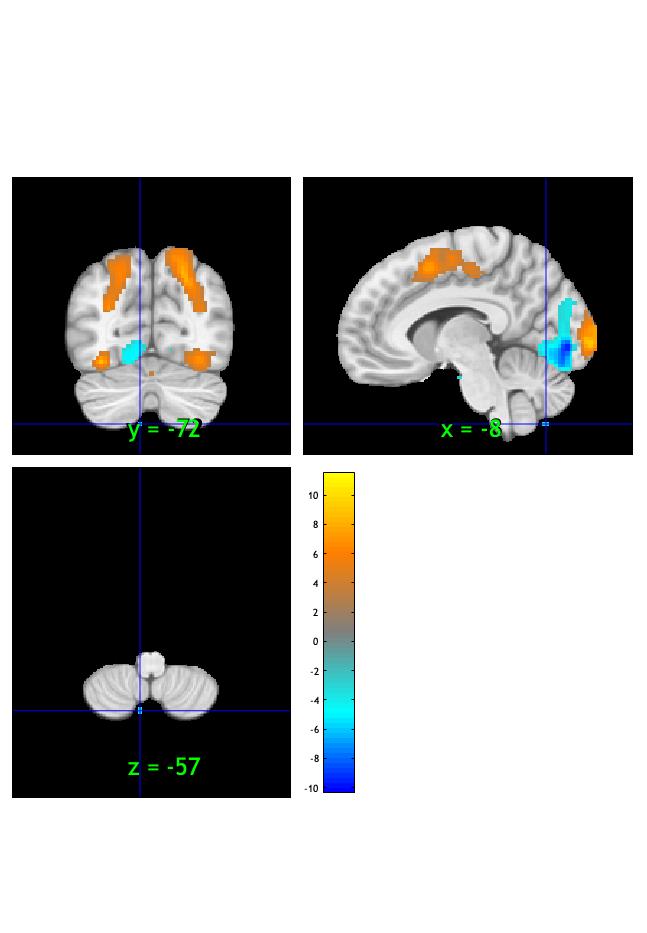

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:08:21 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


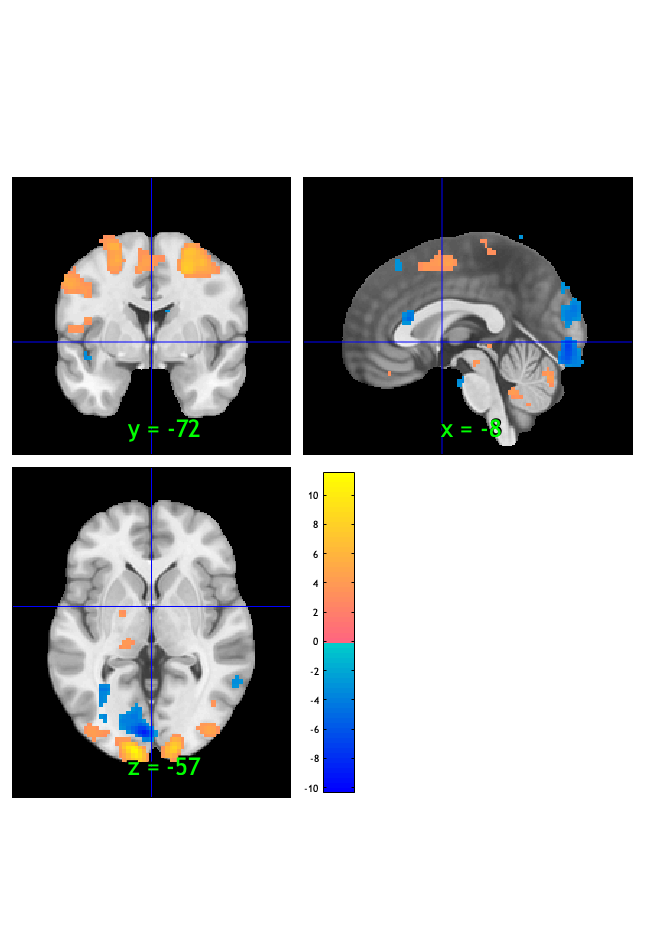

orthviews(fdr_t);

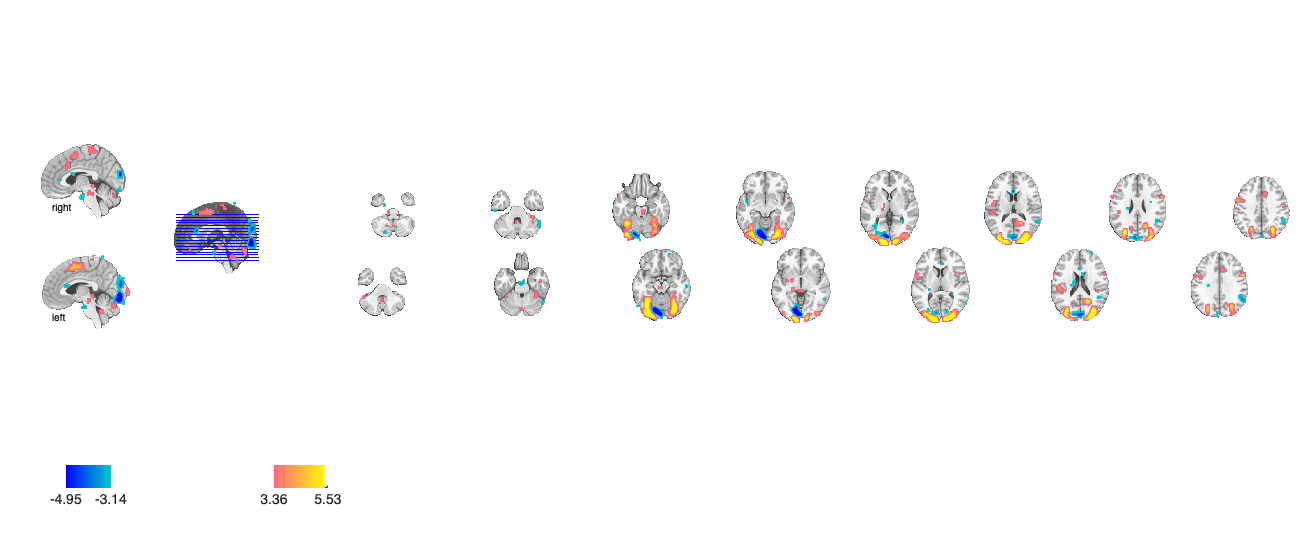

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 187 voxels displayed, 7859 not displayed on these slices
sagittal montage:  91 voxels displayed, 7955 not displayed on these slices
sagittal montage: 149 voxels displayed, 7897 not displayed on these slices
axial montage: 1371 voxels displayed, 6675 not displayed on these slices
axial montage: 1618 voxels displayed, 6428 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### Cognitive only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high     words_high  
    _________    _________________    __________    _____________

    -0.19098     {'disorder'     }     0.22182      {'visual'   }
    -0.19074     {'trait'        }     0.18747      {'execution'}
    -0.17464     {'negative'     }     0.18494      {'movements'}
    -0.17462     {'positive'     }     0.16658      {'objects'  }
    -0.16043     {'affect'       }      0.1663      {'rotation' }
    -0.15662     {'personal'     }     0.16417      {'object'   }
    -0.15611     {'schizophrenia'}     0.16043      {'hand'     }
    -0.15564     {'age'          }     0.15998      {'naming'   }
     -0.1545     {'social'       }     0.15813      {'motor'    }
    -0.15407     {'rating'       }

Cognitive only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0222	-3.5872	0.0006	1.0000	***
Cog Wholebrain	0.0157	4.2087	0.0001	1.0000	***
Emo Wholebrain	0.0070	1.0314	0.3058	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.02221     0.0061828    -3.5922    0.00060056    -0.42334
    {'Cog Wholebrain' }     0.015689     0.0037266       4.21    7.3692e-05     0.49615
    {'Emo Wholebrain' }    0.0069693     0.0067629     1.0305       0.30626     0.12145



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [19.0009 20.0009 21.0009]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.021806     0.0061046    -3.5721    0.00064085    -0.42098
    {'Cog Wholebrain' }     0.015478     0.0035878     4.3142    5.0864e-05     0.50843
    {'Emo Wholebrain' }    0.0066324     0.0066325    0.99997       0.32072     0.11785



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [22.0009 23.0009 24.0009]


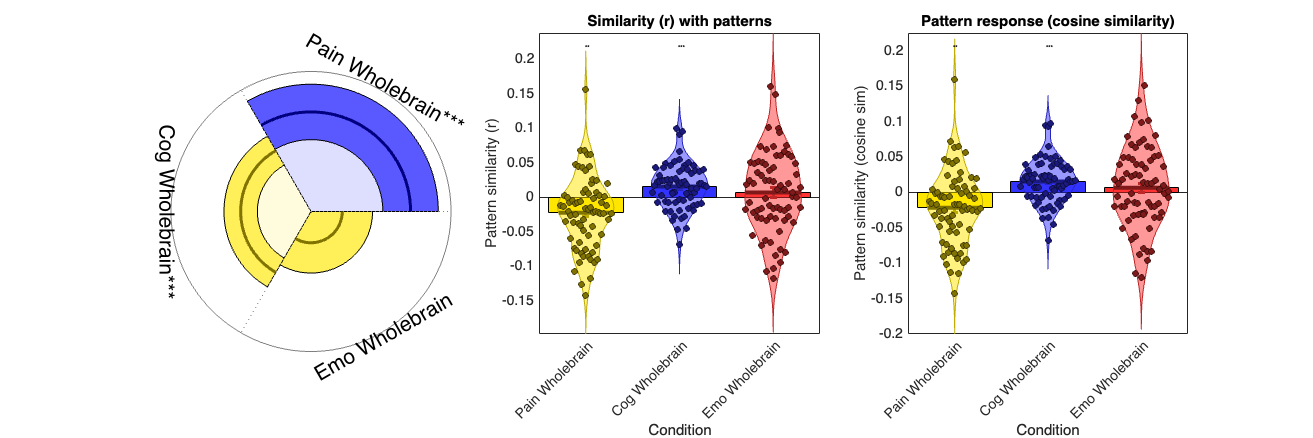

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;

# General dummy maps 

# cue effect (high > low)

#### General :: load dataset

clear all;
close all;

contrast_of_interest = 'G_simple_CUE_cue_high_gt_low'

contrast_of_interest = 'G_simple_CUE_cue_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue_rampplateau/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy
    'G_simple_CUE_cue_high_gt_low',...
    'P_VC_STIM', 'V_PC_STIM', 'C_PV_STIM'

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 28753056 bytes
Loading image number:    72
Elapsed time is 3.403125 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6896249  Bit rate: 22.72 bits


#### General :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:00 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### General :: Plot diagnostics, before l2norm

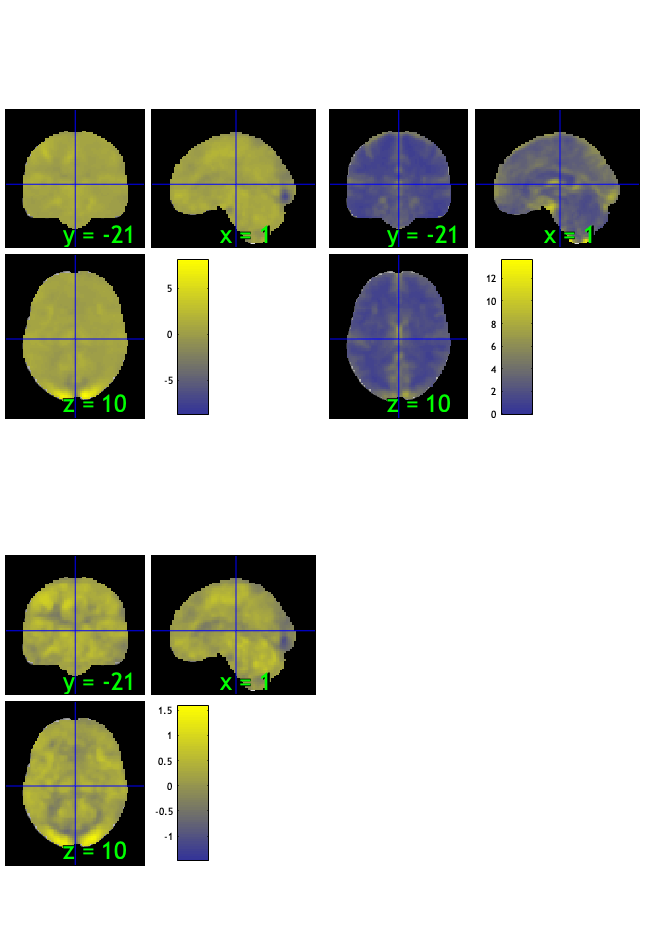

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.33%
Expected 3.60 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 8 48 
Uncorrected: 6 images		Cases 8 13 34 37 48 61 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.61%
Expected 3.60 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 36 38 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

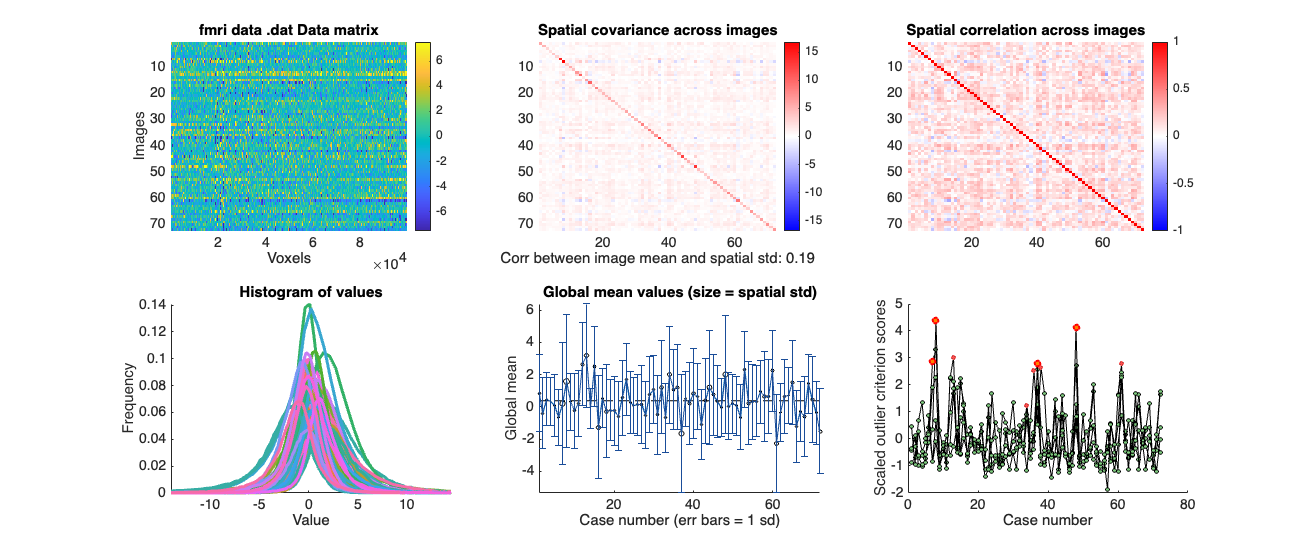

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:26 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

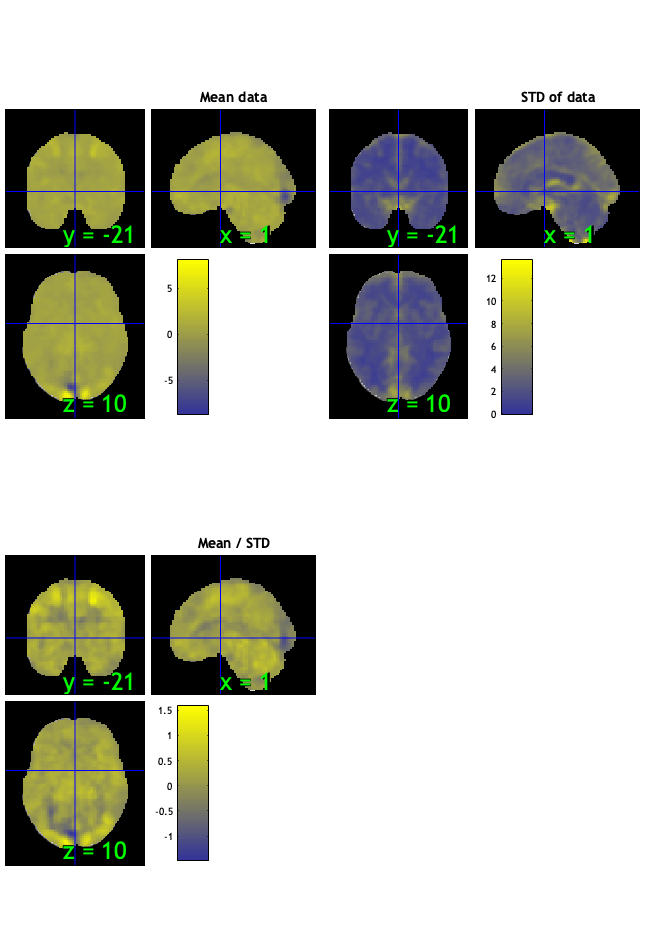

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### General :: run robfit

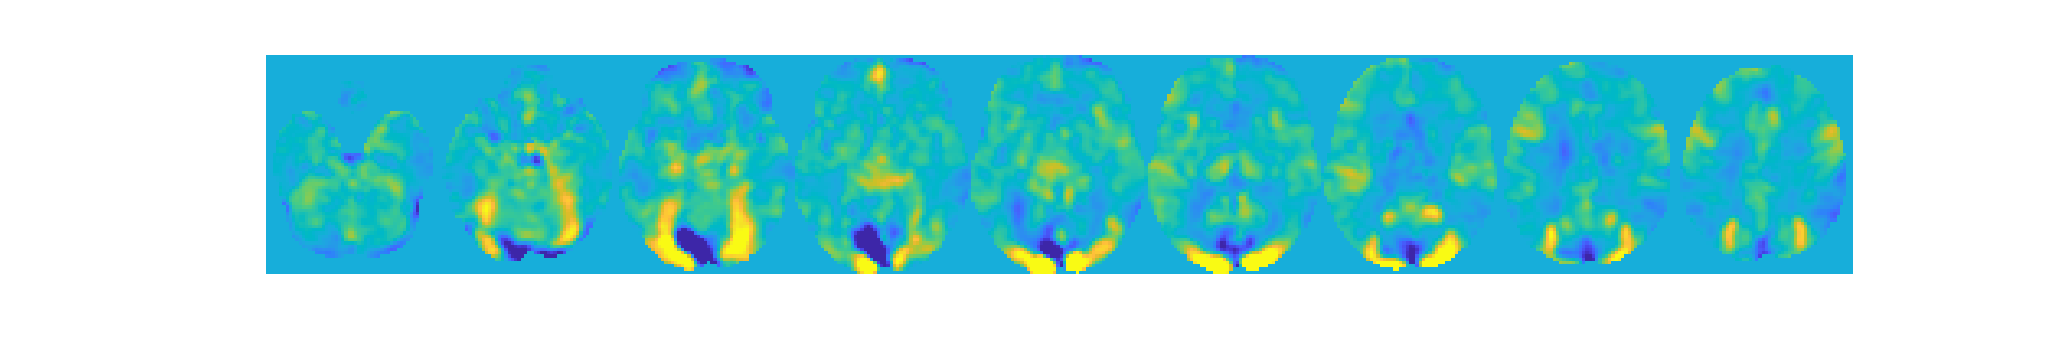

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### General :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 72


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 68


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0033"    "participants that are outliers:... sub-0035"    "participants that are outliers:... sub-0084"    "participants that are outliers:... sub-0098"



disp(n);

    {'sub-0033'}    {'sub-0035'}    {'sub-0084'}    {'sub-0098'}



#### General :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### General :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


orthviews(t);

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:32 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


drawnow, snapnow;

unc_t = threshold(t, .01, 'unc');


Image   1
 93 contig. clusters, sizes   1 to 24948
Positive effect: 23826 voxels, min p-value: 0.00000000
Negative effect: 2884 voxels, min p-value: 0.00000000


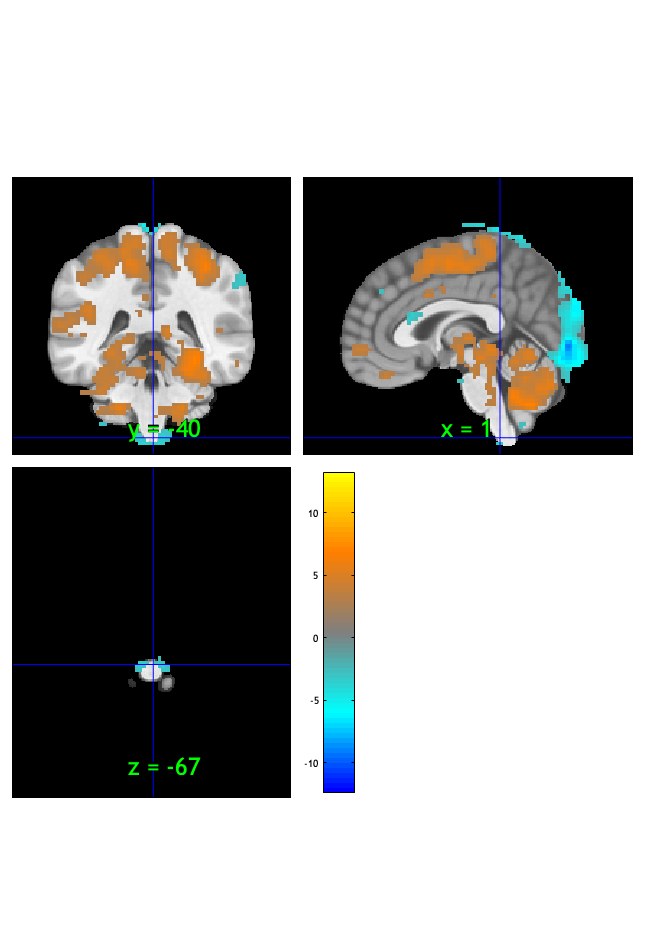

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:35 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(unc_t);

drawnow, snapnow;



fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.014562

Image   1
 94 contig. clusters, sizes   1 to 26985
Positive effect: 25800 voxels, min p-value: 0.00000000
Negative effect: 3279 voxels, min p-value: 0.00000000


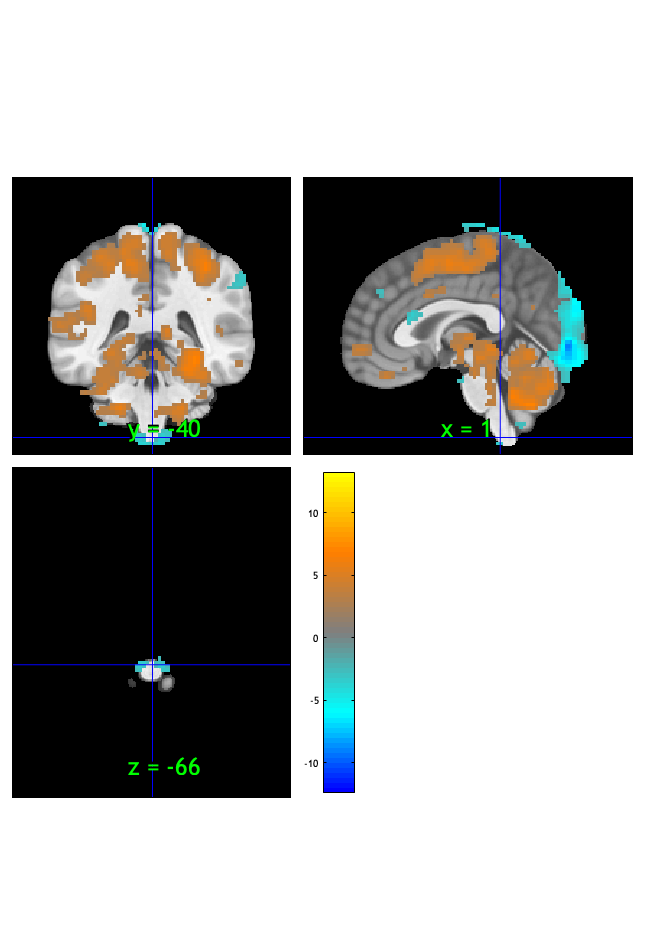

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:36 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000107

Image   1
 64 contig. clusters, sizes   1 to 8638
Positive effect: 9935 voxels, min p-value: 0.00000000
Negative effect: 774 voxels, min p-value: 0.00000000


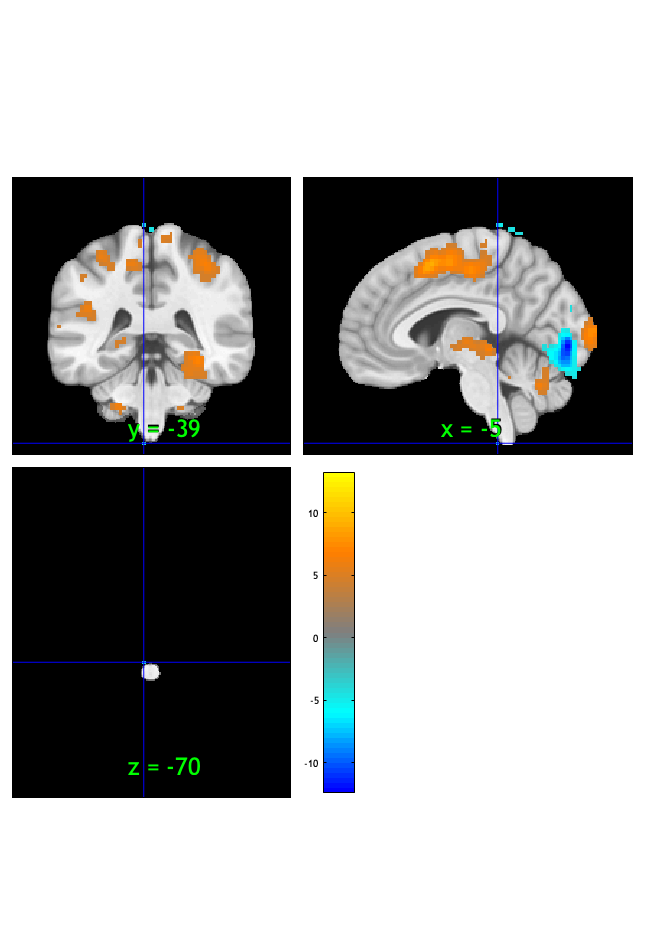

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              16:09:37 - 02/11/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


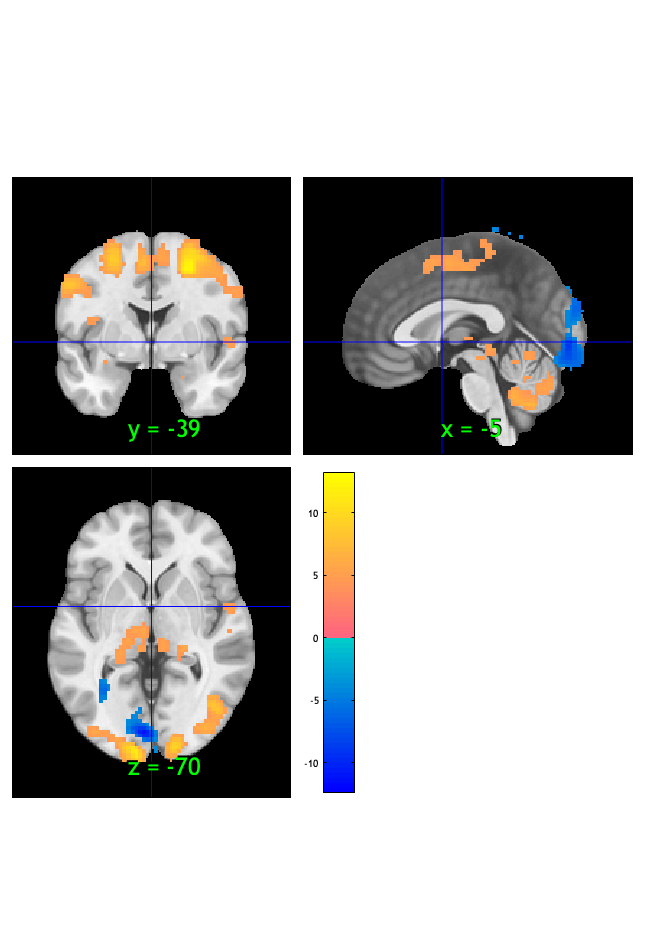

orthviews(fdr_t);

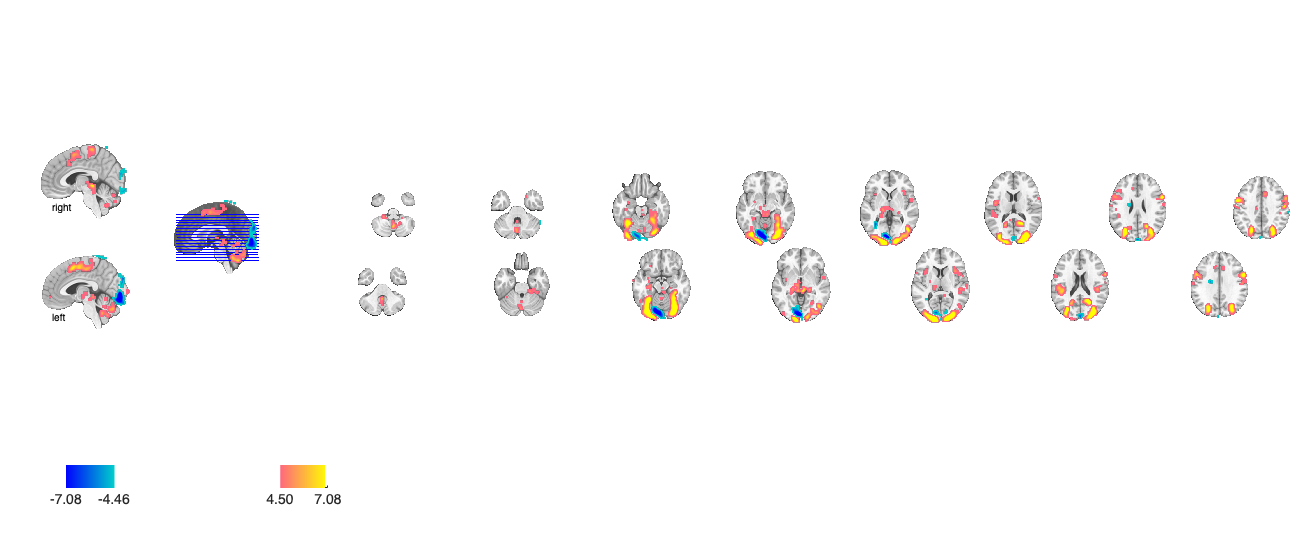

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 266 voxels displayed, 10443 not displayed on these slices
sagittal montage: 142 voxels displayed, 10567 not displayed on these slices
sagittal montage: 222 voxels displayed, 10487 not displayed on these slices
axial montage: 1785 voxels displayed, 8924 not displayed on these slices
axial montage: 2082 voxels displayed, 8627 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### General :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high       words_high   
    _________    _________________    __________    ________________

    -0.19898     {'trait'        }      0.1831      {'execution'   }
    -0.19597     {'disorder'     }     0.18206      {'visual'      }
    -0.16416     {'age'          }     0.16947      {'movements'   }
    -0.15249     {'schizophrenia'}     0.16159      {'naming'      }
    -0.14591     {'personal'     }     0.15821      {'motor'       }
    -0.14181     {'risk'         }      0.1572      {'planning'    }
    -0.13964     {'person'       }     0.15483      {'rotation'    }
    -0.13885     {'positive'     }     0.14904      {'sensorimotor'}
    -0.13821     {'judgments'    }     0.14859      {'overt'       }
 

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

General** :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0282	-4.5616	0.0000	1.0000	***
Cog Wholebrain	0.0146	3.7556	0.0004	1.0000	***
Emo Wholebrain	0.0136	2.3149	0.0235	1.0000	*
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error      T           P         Cohens_d
    ___________________    __________    _________    ______    __________    ________

    {'Pain Wholebrain'}    -0.028236     0.0061893    -4.562    2.0672e-05    -0.53764
    {'Cog Wholebrain' }     0.014627     0.0038946    3.7558    0.00035085     0.44262
    {'Emo Wholebrain' }     0.013624     0.0058852     2.315       0.02351     0.27282



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [20.0010 21.0010 22.0010]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Warnin


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.026479       0.00602    -4.3985     3.754e-05    -0.51837
    {'Cog Wholebrain' }     0.014012     0.0037673     3.7195    0.00039574     0.43834
    {'Emo Wholebrain' }      0.01246     0.0056625     2.2005      0.031029     0.25933



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {72×3 cell}
        text_han: {72×3 cell}
       point_han: {72×3 cell}
    star_handles: [23.0010 24.0010 35.0001]


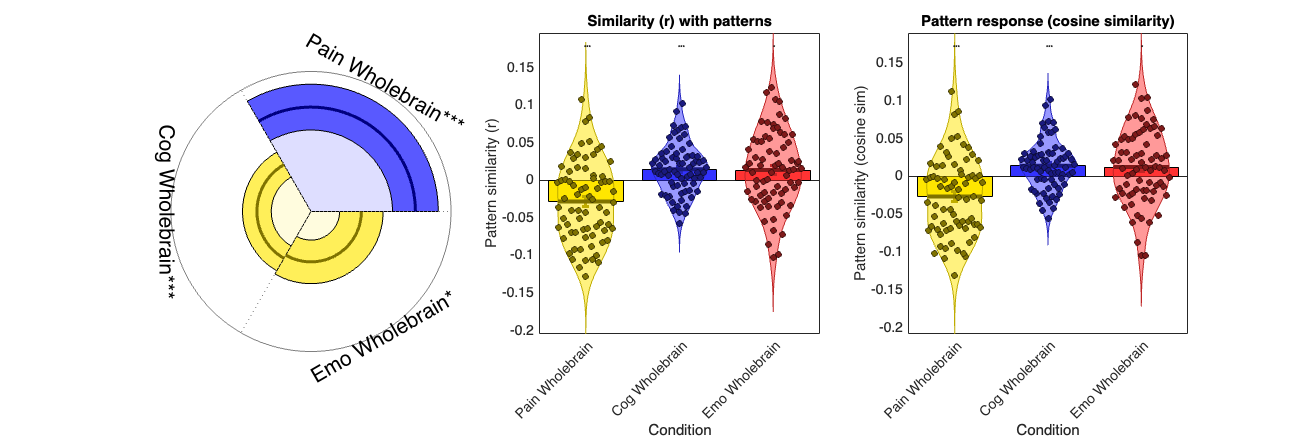

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')


% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);